Let's create some Signals:

The signal Represents a Sine signal which has been sampled with a sample Frequency "fs", a recordingtime "len"

The characteristics of the signal ar defined by its angular frequency w=2*pi*f

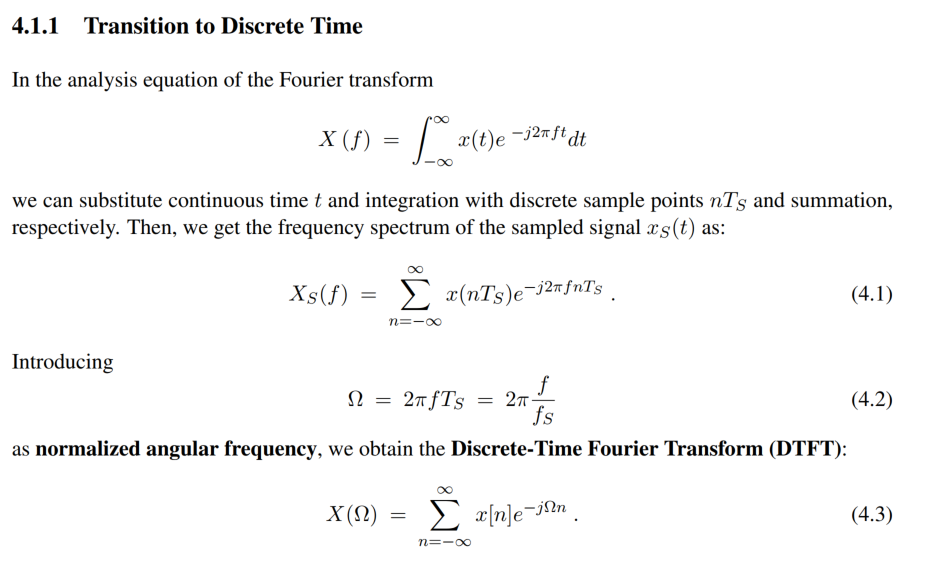

N=16;%defines the amount of sample points in one second [number]
Ts=1/N; %defines the time between two sample points. [s]
fs=1/Ts;%is the sample frequency "how many times a second do we look at the signal" [Hz]
len=1;%defines how long the signal is we are looking at
f=1; %signal frequency in [Hz]
w=2*pi*f %angular frequency, defines how long it takes a signal to complete one cycle

w = 6.2832

u_circ=[0:1:2*pi]; %is the circumfurance of a circle
a=exp(j*w);%is a spinning arrow;
n1=[0:Ts:len-1]; %our timeline in stepsizes of Tn
n2=[0:1:len/Ts-1];%our timeline in stepsizes of 1 

Let's First try to understand the angular frequency:

- f is 1/f*[s]: Number per Second

- 2*pi is the length of our circle, we can imagine it as a line of length 2*pi, or as roundtrips around the circle: 2*pi: TripsAroundCircle

if we complete it now, we can rewrite this as w=Number*TripsAroundCircle/Second so w just tells us the number of trips around a circle per second. 

So if we multiply it by some time, we have the amount of "TripsAroundTheCircle" completed in that time. So let's just do that, let's multiply this with your time. 


if false
    t_max=1 ; 
    t=[0:0.1:t_max];%our timeline
    
    a=exp(j*w*t);
    figure(1)
    subplot(1,2,1)
    plot(real(a),imag(a),'-o');
    axis([-1 1 -1 1]);
    subplot(1,2,2)
    plot(imag(a),'-o');
end

Alright we know now, that t defines how many times we go around our circle. We can also beautifully see, that the imaginary part of our singal is a sine signal. We can also see, when t becomes bigger than one that our wave starts to repeat itself. But so far, we can only draw signal with periodicity of 1[Hz], so how can we draw a signal of periodicity 2 or higher?

A signal with higher frequency goes around the circle twice in one second. Let's see what happens if we let t_max at one but we increase our frequency?

if false
    f=1; %signal frequency in [Hz]
    %t_max=1 ; 
    %Ts=0.01
    t=[0:Ts:t_max];%our timeline
    w=2*pi*f %angular frequency, defines how long it takes a signal to complete one cycle
    a=exp(j*w*t);
    figure(2)
    subplot(1,2,1)
    plot(real(a),imag(a),'-o');
    axis([-1 1 -1 1]);
    subplot(1,2,2)
    plot(imag(a),'-o');
end

Alright what we can see her, is, that if we increase our frequency something weird happens. We have less points to display one period. Let's see what happens if we increase our stepsize.

if false
    f=1.2; %signal frequency in [Hz]
    %t_max=1 ; 
    Ts=0.01
    t=[0:Ts:t_max];%our timeline
    w=2*pi*f %angular frequency, defines how long it takes a signal to complete one cycle
    a=exp(j*w*t);
    figure(3)
    subplot(1,2,1)
    plot(real(a),imag(a),'-o');
    axis([-1 1 -1 1]);
    subplot(1,2,2)
    plot(imag(a),'-o');
end

So the Stepsize defines how good we can represent our signal, our stepsize is Ts=1/fs so fs=1/Ts

if false
    f=1; %signal frequency in [Hz]
    t_max=1 ; 
    Ts=0.39
    t=[0:Ts:t_max];%our timeline
    w=2*pi*f %angular frequency, defines how long it takes a signal to complete one cycle
    a=exp(j*w*t*Ts);
    figure(3)
    subplot(1,2,1)
    plot(real(a),imag(a),'-o');
    axis([-1 1 -1 1]);
    subplot(1,2,2)
    plot(imag(a),'-o');
end

what happens if we change our time array

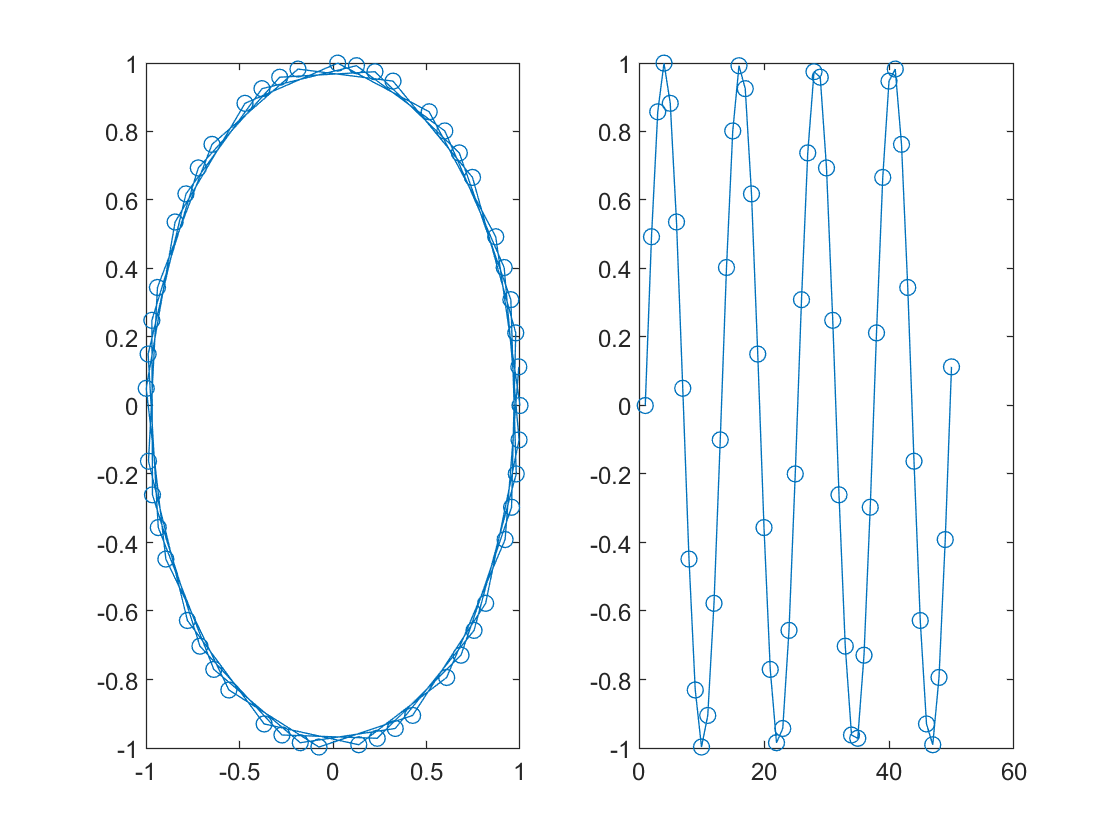

if true
    f=4.1; %signal frequency in [Hz]
    t_max=1 ; 
    Ts=0.02;
    t=[0:1:t_max/Ts-1];%our timeline
    w=2*pi*f ;%angular frequency, defines how long it takes a signal to complete one cycle
    a=exp(j*w*Ts*t);
    figure(3)
    subplot(1,2,1)
    plot(real(a),imag(a),'-o');
    axis([-1 1 -1 1]);
    subplot(1,2,2)
    plot(imag(a),'-o');
end